# Estimation, Filtering and Detection

## Homework 2C: Asynchronous Sampling

## Timur Uzakov

## MACROS

clear all;
storeFigures = false; % set true if you want to save plots

## Problem 1:

% Y(s) = 1/(1+s*tau)^2 *(U(s)+D(s))
% Find continusous-time stochastic state space model
% Create disturbance as a Wiener process
% Intensity of disturbance Q = 0.001

Qc  = 0.001;
Rc  = 0.01*0.01;
tau = 50;
T = 1000;

% Solution
% Continuous-time system

% Wiener Process 
N = 5000;
dt = T/N;
dW = zeros(1,N);                % preallocate arrays ...
W = zeros(1,N);                 % for efficiency
dW(1) = Qc*sqrt(dt)*randn();    % first approximation outside the loop ...
W(1) = dW(1);                   % since W(0) = 0 is not allowed
for j = 2:N
    dW(j)= Qc*sqrt(dt)*randn(); % general increment
    W(j) = W(j-1) + dW(j);
end
figure(1);
plot([0:dt:T],[0,W],'r-')       % plot W against t
xlabel('t','FontSize',16)
ylabel('W(t)','FontSize',16,'Rotation',0)
title("Wiener process");

% mean and variance
MeanWiener = mean(W)

MeanWiener = -2.2170e-04

VarianceWiener = var(W)

VarianceWiener = 1.0779e-04




sys = tf(1,[tau^2 2*tau 1]);

step_input = ones(1,N+1);
disturbance = [0,W];
response = lsim(sys,step_input+disturbance,[0:dt:T]);
response_original = lsim(sys,step_input,[0:dt:T]);

figure(2);
plot([0:dt:T],response);
ylabel("Amplitude");
xlabel("Time (seconds)");
title("Continuous-time stochastic state-space model step response");
hold on
plot([0:dt:T],response_original);
legend("With disturbance","Original");

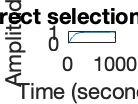

legend show
fix_ylim = ylim;

% . 
% x = Ax + Bu + Gw      {State equation}
% y = Cx + Du +  v      {Measurements}
[A,B,C,D] = tf2ss(1,[tau^2 2*tau 1]);
G = [1;0];
sys = ss(A,[B G],C,[D 0]);
step_input = ones(1,N+1);
disturbance = [0,W];
%% verification of stochastic state space model derivation
response = lsim(sys,[step_input;disturbance],[0:dt:T]);
figure;
plot([0:dt:T],response);
ylabel("Amplitude");
xlabel("Time (seconds)");
title("Verification of correct selection of state-space model");

## Problem 2:

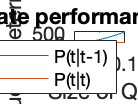

% Find discrete-time model
% Find Kalman filter
% Ts = 20s
% Evaluate predicted and filtered values
Ts = 20;
q_s = 0.001:0.0005:0.1;
P_s = zeros(length(q_s),1);
Z_s = zeros(length(q_s),1);
for i = 1:length(q_s)
    Qn = q_s(i)*eye(size(A,1));
    Rn = Rc*eye(size(C,1));
    [kest,L,P,M,Z] = kalmd(sys,Qn,Rn,Ts);
    P_s(i) = det(P); % prediction co-variance p(t|t-1)
    Z_s(i) = det(Z); % filtering co-variance P(t|t)
end
figure(3);
plot(q_s,P_s);
hold on;
plot(q_s,Z_s);
ylabel("Value of determinant");
xlabel("Size of Qn");
title("Comparison of steady state performances for different q parameters");
legend("P(t|t-1)","P(t|t)");

legend show

P_min = 1000000;
for i = 1:length(q_s)
    if (P_s(i)<P_min)
        disp("Found minimum")
        P_min = P_s(i);
        i_min = i;
    end
end

Found minimum


Qn = q_s(i_min)*eye(size(A,1));
Rn = 0.1*eye(size(C,1));
[kest,L,P,M,Z] = kalmd(sys,Qn,Rn,Ts);
P %minimal prediction co-variance p(t|t-1)

P =     0.0250    0.0030
    0.0030   62.1751


Z %minimal filtering co-variance P(t|t)

Z =     0.0250    0.0030
    0.0030   62.0517


## Problem 3:

% Find Kalman Filter models
% Use asynchronous sampling with controller computation time
% Tc = 10/1/0.1/s
% Compare properties of noise models
% Evaluate P (predicted value)

Ts = 20;
Tcs = [10 1 0.1];
B = [B G];
for i = 1:3
    Tc = Tcs(i);
    etta = (Ts-Tc)/Ts;
    Aasync = expm(A*Ts);
    Basync = inv(A)*(expm(A*Ts)-expm(A*0))*B;
    Casync = C*expm(A*etta*Ts);
    Dasync = C*inv(A)*(expm(A*etta*Ts)-expm(A*0))*B;
    
    Q = Qc*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
    S = Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    R = Rc + C*Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    disp("Tc")
    disp(Tcs(i))
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Q,R,S);
    P
end

Tc


    10



P = 	1.0e+09 *

    0.0669    0.5210
    0.5210    4.0548


Tc


     1



P = 	1.0e+04 *

    0.6902    0.9280
    0.9280    4.0247


Tc


    0.1000



P = 	1.0e+04 *

    0.0714    0.0960
    0.0960    1.0645



%% Conclusion: the longer the Tc, the worse is prediction covariance

## Problem 4:

% Show impact of negletting S in case of asynchronous sampling
for i = 1:3
    Tc = Tcs(i);
    etta = (Ts-Tc)/Ts;
    Aasync = expm(A*Ts);
    Basync = inv(A)*(expm(A*Ts)-expm(A*0))*B;
    Casync = C*expm(A*etta*Ts);
    Dasync = C*inv(A)*(expm(A*etta*Ts)-expm(A*0))*B;
    
    Q = Qc*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
    S = Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    R = Rc + C*Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    disp("Tc")
    disp(Tcs(i))
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Q,R,S);
    disp("With S")
    P
    disp("Value of determinant with S")
    disp(det(P))
    disp("With S=0")
    [kest,L,P,M,Z] = kalman(ss(Aasync,Basync,Casync,Dasync,Ts),Q,R);
    P
    disp("Value of determinant without S")
    det(P)
end

Tc


    10



With S


P = 	1.0e+09 *

    0.0669    0.5210
    0.5210    4.0548


Value of determinant with S


   5.5126e+10



With S=0


P = 	1.0e+09 *

    0.0669    0.5210
    0.5210    4.0548


Value of determinant without S


ans = 5.5126e+10

Tc


     1



With S


P = 	1.0e+04 *

    0.6902    0.9280
    0.9280    4.0247


Value of determinant with S


   1.9168e+08



With S=0


P = 	1.0e+04 *

    1.1686    1.5715
    1.5715    6.5784


Value of determinant without S


ans = 5.2181e+08

Tc


    0.1000



With S


P = 	1.0e+04 *

    0.0714    0.0960
    0.0960    1.0645


Value of determinant with S


   6.6816e+06



With S=0


P = 	1.0e+05 *

    0.0767    0.1032
    0.1032    1.1069


Value of determinant without S


ans = 7.4302e+08

%% Conclusion: inclusion of S improves prediction covariance for 10 times for Tc = 0.1

## Problem 5:

% Evaluate filtered P(t|t) 
% Use filter design for system with not correlated noise (S=0)
for i = 1:3
    Tc = Tcs(i);
    etta = (Ts-Tc)/Ts;
    
    Q = Qc*inv(A+A')*(expm((A+A')*Ts) -expm((A+A')*0));
    S = Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    R = Rc + C*Qc*inv(A+A')*(expm((A+A')*etta*Ts) -expm((A+A')*0))*C';
    
    A_decor = A - S*inv(R)*C;
    B_decor = B - S*inv(R)*D;
    Q_decor = Q - S*inv(R)*S';
    
    R = R;
    
    disp("State covariance matrix P(t|t) for system model with decorrelated noise")
    
    [kest,L,P,M,Z] = kalman(ss(A_decor,B_decor,C,D,Ts),Q_decor,R);
    Tc
    Z
    det(Z)
end

State covariance matrix P(t|t) for system model with decorrelated noise


Tc = 10

Z = 	1.0e+05 *

    4.5744   -0.0003
   -0.0003    0.0063


ans = 2.8917e+08

State covariance matrix P(t|t) for system model with decorrelated noise


Tc = 1

Z = 	1.0e+05 *

    3.2086    0.0264
    0.0264    0.4086


ans = 1.3102e+10

State covariance matrix P(t|t) for system model with decorrelated noise


Tc = 0.1000

Z = 	1.0e+04 *

    9.1118    1.6578
    1.6578    5.5383


ans = 4.7715e+09

% Conclusion:
% The best values of filtering co-variance P(t|t) is achieved with 
% small Tc = 1s

## Additional tools

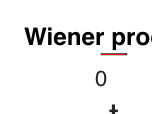

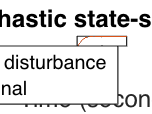

% Storing figures
if storeFigures
    for i=1:3
        filename = strcat('figure_',num2str(i));
        foldername = './figures/';
        saveas(figure(i),fullfile(foldername,filename),'jpg');
    end
end